%==========================================================================
% Author:    Naghmeh Akhavan, PhD (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Purpose:
%   Fit a 2-component Gaussian mixture model (GMM) to z = log(|N|) for Human
%   REM cycles, where |N| is the NREM duration within the inter-REM interval
%   (IREM). The script uses a "DROP long-wake cycles" dataset produced by an
%   upstream filtering step (preferred), so the same long-wake rule can be
%   enforced consistently across the pipeline.
%
% Long-wake policy:
%   - Preferred input: combined_out/filtered_out/BigResult_noLongWake_<thr>min.mat
%       (variable: Filtered_BigResultTable)
%     This table already excludes cycles containing a Wake bout >= threshold.
%
% Analysis:
%   1) Build pooled cycle table in minutes:
%        RP_min   = REMpre / 60
%        N_min    = NREM   / 60   (|N|)
%        IREM_min = IREM   / 60
%      Keep only cycles with REMpre > 0 and NREM > 0 (finite).
%   2) Fit toolbox-free EM GMM (K=2) to z = log(N_min):
%        - once on all pooled cycles ("lumped")
%        - separately within equal-count REMpre bins (default: quartiles)
%   3) Plot histogram of z with mixture components overlaid.
%
% Outputs:
%   - Figure 1: Lumped histogram of log(|N|) with two Gaussian components
%   - Figure 2: Per-REMpre-bin histograms + fitted mixtures
%   - Optional saving if SAVE_FIGS = true
%
% Last updated: 2026-01-16
%==========================================================================


clear; clc;


## Paths

combinedFolder   = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';


## Long-wake threshold

WAKE_BREAK_MIN   = 2;   % set to the threshold you dropped with (e.g., 10)
filteredMat      = fullfile(combinedFolder, 'filtered_out', ...
                     sprintf('BigResult_noLongWake_%dmin.mat', WAKE_BREAK_MIN));

% Fallback
matR_fallback    = fullfile(combinedFolder, 'Combined_BigResultTable.mat');



## Per-REMpre equal-count bins (quartiles)

nREMpreBins      = 4;

% Histogram bins for plots
nbinsHist        = 60;

% Save figures
SAVE_FIGS        = false;
figOut           = fullfile(combinedFolder, 'figs_out');
if SAVE_FIGS && ~isfolder(figOut), mkdir(figOut); end


## Load data

if isfile(filteredMat)
    Sf = load(filteredMat);
    assert(isfield(Sf, 'Filtered_BigResultTable'), ...
        'Filtered file lacks Filtered_BigResultTable: %s', filteredMat);
    T = Sf.Filtered_BigResultTable;          % kept cycles (after DROP)
    fprintf('Loaded kept cycles (wake >= %d min DROPPED): %s\n', WAKE_BREAK_MIN, filteredMat);
else
    warning('Filtered file not found:\n  %s\nUsing UNFILTERED Combined_BigResultTable instead.', filteredMat);
    assert(isfile(matR_fallback), 'Missing Combined_BigResultTable.mat (run Step 3).');
    Sfb = load(matR_fallback);
    assert(isfield(Sfb, 'Combined_BigResultTable'));
    T = Sfb.Combined_BigResultTable;
end


% Normalize key columns / types
if ~ismember("REM_Cycle_Index", string(T.Properties.VariableNames))
    T.REM_Cycle_Index = strings(height(T),1);
end
T.REM_Cycle_Index = string(T.REM_Cycle_Index);

% Numeric metrics present & double
needNum = ["REMpre","NREM","IREM","Wake","Movement"];
for v = needNum
    if ~ismember(v, string(T.Properties.VariableNames))
        T.(v) = NaN(height(T),1);
    end
    T.(v) = double(T.(v));
end
% If IREM missing or NaN-only, reconstruct as NREM + Wake + Movement
if all(isnan(T.IREM)) && all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
    T.IREM = T.NREM + T.Wake + T.Movement;
end

% Species (all Human in this project)
if ~ismember("Species", string(T.Properties.VariableNames))
    T.Species = repmat("Human", height(T), 1);
else
    T.Species = string(T.Species);
    T.Species(T.Species=="") = "Human";
end


## Build pooled human cycles (minutes, kept only)

RP_min   = T.REMpre / 60;      % REMpre minutes
N_min    = T.NREM   / 60;      % |N| minutes (NREM only)
IREM_min = T.IREM   / 60;      % inter-REM minutes (incl. Wake + Movement)

% Valid pooled cycles: positive REMpre and positive NREM (|N|)
ok = isfinite(RP_min) & (RP_min > 0) & isfinite(N_min) & (N_min > 0);
P = table(RP_min(ok), N_min(ok), IREM_min(ok), ...
    'VariableNames', {'RP_min','N_min','IREM_min'});

fprintf('Valid kept pooled cycles (DROP, wake >= %d min): %d of %d kept.\n', ...
        WAKE_BREAK_MIN, height(P), height(T));

Valid kept pooled cycles (DROP, wake >= 2 min): 4372 of 5022 kept.


## Lumped GMM fit (all cycles together)

% z = log(|N|) in minutes
z = log(P.N_min);
z = z(isfinite(z));

K = 2;
gmmOpts = struct('nStarts',30,'maxIter',200,'tol',1e-6, ...
                 'trimFrac',0.01, 'sdMin',0.08, 'sdMax',3.0, ...
                 'clipQuantiles',[0.5 99.5], 'verbose',false);

[wL, muL, sdL, infoL] = fit_gmm_1d(z, K, gmmOpts);

% Mixture pdf on grid
xx = linspace(min(z), max(z), 400);
yy = gmm_pdf_grid(xx, wL, muL, sdL);


## Plot lumped Histogram + components

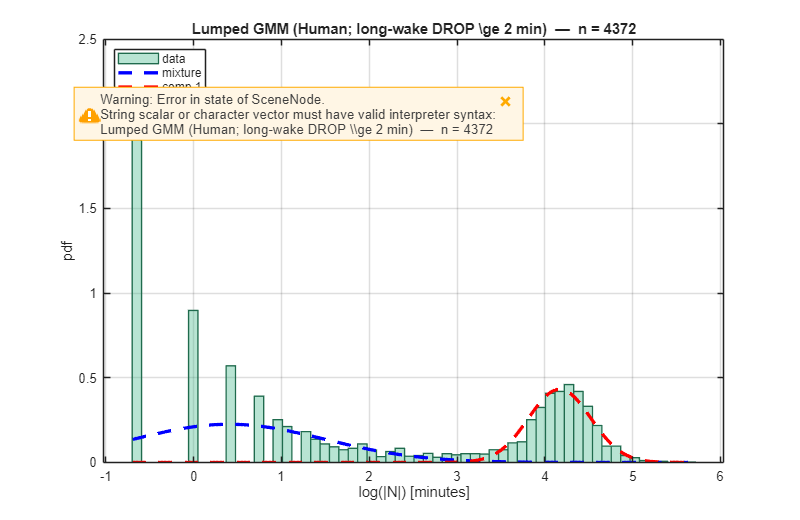

f1 = figure('Color','w','Position',[120 120 800 520]);

face = [0.2 0.7 0.5];          % teal fill (color)
edge = face * 0.6;             % slightly darker teal for the outline

histogram(z, nbinsHist, ...
    'Normalization','pdf', ...
    'FaceColor',face, 'FaceAlpha',0.35, ...
    'EdgeColor',edge, 'LineWidth',1.);

hold on;
%plot(xx, yy, 'm-', 'LineWidth',2.2);  % total mixture (optional; keep if you like seeing the sum)
plot(xx, wL(1)*gauss_pdf(xx, muL(1), sdL(1)), 'b--', 'LineWidth',2.5);
plot(xx, wL(2)*gauss_pdf(xx, muL(2), sdL(2)), 'r--', 'LineWidth',2.5);
grid on; box on;
xlabel('log(|N|) [minutes]');
ylabel('pdf');
title(sprintf('Lumped GMM (Human; long-wake DROP \\ge %d min)  —  n = %d', ...
      WAKE_BREAK_MIN, numel(z)));
legend({'data','mixture','comp 1','comp 2'}, 'Location','northwest');

if SAVE_FIGS
    saveas(f1, fullfile(figOut, sprintf('gmm_lumped_drop_longwake%d.png', WAKE_BREAK_MIN)));
end


## Per-REMpre-bin GMMs

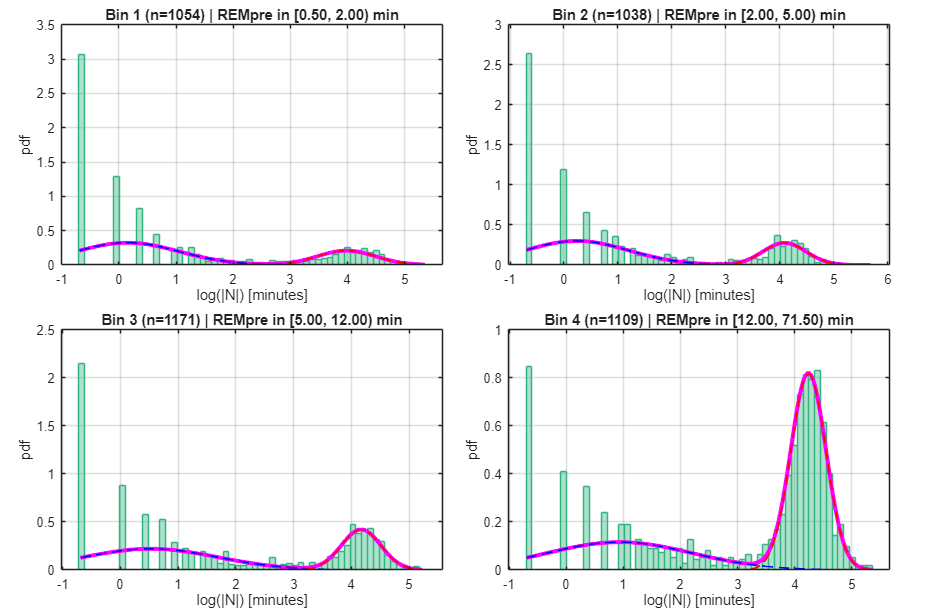

edges = quantile(P.RP_min, linspace(0,1,nREMpreBins+1));
binID  = discretize(P.RP_min, edges);
Bfits  = cell(nREMpreBins,1);

f2 = figure('Color','w','Position',[100 100 980 640]);
tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

% loop over bins
for b = 1:nREMpreBins
    zb = log(P.N_min(binID==b));
    zb = zb(isfinite(zb));
    nexttile;

    if numel(zb) < 50
        histogram(zb, max(10,round(numel(zb)/4)), 'Normalization','pdf', ...
            'FaceColor',[0.2 0.7 0.5], 'FaceAlpha',0.4, 'EdgeColor','none');
        title(sprintf('Bin %d (n=%d) | REMpre in [%.2f, %.2f) min', ...
              b, numel(zb), edges(b), edges(b+1)));
        grid on; box on; xlabel('log(|N|) [minutes]'); ylabel('pdf');
        continue;
    end

    [wB, muB, sdB, infoB] = fit_gmm_1d(zb, K, gmmOpts);
    xxB = linspace(min(zb), max(zb), 350);
    yyB = gmm_pdf_grid(xxB, wB, muB, sdB);

 % histogram + total mixutre + two weighted components
    histogram(zb, nbinsHist, 'Normalization','pdf', ...
              'FaceColor',[0.2 0.7 0.5], 'FaceAlpha',0.4, 'EdgeColor', 1*[0.2 0.7 0.5]);
    hold on;
    plot(xxB, yyB, 'm-', 'LineWidth',3.0);  % total mixture (optional)
    plot(xxB, wB(1)*gauss_pdf(xxB, muB(1), sdB(1)), 'b--', 'LineWidth',1.2);
    plot(xxB, wB(2)*gauss_pdf(xxB, muB(2), sdB(2)), 'r--', 'LineWidth',1.2);
    grid on; box on;
    xlabel('log(|N|) [minutes]'); ylabel('pdf');
    title(sprintf('Bin %d (n=%d) | REMpre in [%.2f, %.2f) min', ...
          b, numel(zb), edges(b), edges(b+1)));

    Bfits{b} = struct('w',wB,'mu',muB,'sd',sdB,'info',infoB,'n',numel(zb), ...
                      'edges',[edges(b) edges(b+1)]);
end


%title(tl, sprintf('Per-REMpre-bin  GMMs  (Human; long-wake >= %d min)', WAKE_BREAK_MIN));
if SAVE_FIGS
    saveas(f2, fullfile(figOut, sprintf('gmm_bins_drop_longwake%d.png', WAKE_BREAK_MIN)));
end


## Functions

% fit_gmm_1d: wrap the EM algorithm
% em_core: implements EM iterations
% gmm_pdf_grid: evaluates the mixture density
% gauss_pdf: plain normal pdf formula

function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
x = x(:);
x = x(isfinite(x));
if nargin<3, opts = struct; end
g = @(f,def) (isfield(opts,f) && ~isempty(opts.(f))) .* opts.(f) + ...
             ( ~isfield(opts,f) || isempty(opts.(f)) ) .* def;
nStarts  = g('nStarts', 15);
maxIter  = g('maxIter', 200);
tol      = g('tol', 1e-6);
trimFrac = g('trimFrac', 0.01);
sdMin    = g('sdMin', 0.08);
sdMax    = g('sdMax', 3.0);
cq       = g('clipQuantiles', [0.5 99.5]);  % in percent
verbose  = g('verbose', false);

% clip extremes a bit to stabilize
qlo = quantile(x, cq(1)/100);
qhi = quantile(x, cq(2)/100);
x = x(x>=qlo & x<=qhi);
n = numel(x);

% precompute
log2pi = log(2*pi);

bestLL = -inf; best = [];
for s = 1:nStarts
    % --- initialize by quantiles with small jitter
    mu0 = linspace(quantile(x,0.2), quantile(x,0.8), K);
    mu0 = mu0 + 0.05*randn(1,K);
    sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
    w0  = ones(1,K)/K;

    [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
    if LL(end) > bestLL
        bestLL = LL(end);
        best = {w1, mu1, sd1, LL};
    end
end
[w, mu, sd, LL] = best{:};
info = struct('loglik',LL,'nStarts',nStarts,'n',n);

if verbose
    fprintf('EM done: LL=%.3f | mu=[%s] | sd=[%s] | w=[%s]\n', ...
        LL(end), num2str(mu,' %.2f'), num2str(sd,' %.2f'), num2str(w,' %.2f'));
end
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
n = numel(x); K = numel(w);
LL = zeros(maxIter,1);
trimN = floor(trimFrac*n);

for it = 1:maxIter
    % E-step: responsibilities
    logp = zeros(n,K);
    for k=1:K
        v = sd(k)^2;
        logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
    end
    % log-sum-exp
    m = max(logp,[],2);
    p = exp(logp - m); s = sum(p,2);
    gamma = p ./ max(s,eps);

    % Trim a few lowest total probs if requested
    if trimN>0
        [~,idx] = sort(s, 'ascend');
        keep = true(n,1); keep(idx(1:trimN)) = false;
    else
        keep = true(n,1);
    end

    Nk = sum(gamma(keep,:), 1);           % effective counts
    w  = Nk ./ max(sum(Nk), eps);
    for k=1:K
        mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k), eps);
        v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k), eps);
        sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
    end

    % log-likelihood
    logp = zeros(sum(keep),K);
    xk   = x(keep);
    for k=1:K
        v = sd(k)^2;
        logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
    end
    m = max(logp,[],2);
    LL(it) = sum(m + log(sum(exp(logp - m),2)));

    if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1)))
        LL = LL(1:it); break;
    end
end
LL = LL(1:it);
end

function y = gmm_pdf_grid(x, w, mu, sd)
% mixture pdf at x (vector)
K = numel(w);
y = zeros(size(x));
for k=1:K
    y = y + w(k)*gauss_pdf(x, mu(k), sd(k));
end
end

function y = gauss_pdf(x, m, s)
% 1-D normal pdf (no toolbox)
y = (1./(s*sqrt(2*pi))) .* exp(-0.5*((x-m)./s).^2);
end
